# Practice 8 - Heated Tank System Analysis

Automation of Thermal Processes First-order transfer function modeling and step response analysis.

clear; clc; close all;

## System Parameters

m  = 10;        % Mass [kg]
Cp = 4200;      % Heat capacity [J/(kg·K)]
A  = 1;         % Surface area [m²]

% Case 1: h = 50 W/(m²·K)
h1 = 50;

% Case 2: h = 100 W/(m²·K)
h2 = 100;

## Calculate Time Constant and Gain for Case 1

tau1 = (m * Cp) / (h1 * A);   % Time constant [s]
K1   = 1 / (h1 * A);          % System gain [K/W]

fprintf('=== Case 1: h = %d W/(m².K) ===\n', h1);

=== Case 1: h = 50 W/(m².K) ===


fprintf('Time constant tau = %.2f s (%.2f min)\n', tau1, tau1/60);

Time constant tau = 840.00 s (14.00 min)


fprintf('System gain K     = %.4f K/W\n', K1);

System gain K     = 0.0200 K/W


fprintf('Steady-state temp rise for 1W input = %.4f K\n\n', K1);

Steady-state temp rise for 1W input = 0.0200 K



## Calculate Time Constant and Gain for Case 2

tau2 = (m * Cp) / (h2 * A);   % Time constant [s]
K2   = 1 / (h2 * A);          % System gain [K/W]

fprintf('=== Case 2: h = %d W/(m².K) ===\n', h2);

=== Case 2: h = 100 W/(m².K) ===


fprintf('Time constant tau = %.2f s (%.2f min)\n', tau2, tau2/60);

Time constant tau = 420.00 s (7.00 min)


fprintf('System gain K     = %.4f K/W\n', K2);

System gain K     = 0.0100 K/W


fprintf('Steady-state temp rise for 1W input = %.4f K\n\n', K2);

Steady-state temp rise for 1W input = 0.0100 K



## Build Transfer Functions

G(s) = K / (tau*s + 1)

G1 = tf(K1, [tau1 1]);   % Case 1: h = 50
G2 = tf(K2, [tau2 1]);   % Case 2: h = 100

fprintf('Transfer Function (h=50):\n');

Transfer Function (h=50):


G1


G1 =
 
    0.02
  ---------
  840 s + 1
 
Continuous-time transfer function.


fprintf('Transfer Function (h=100):\n');

Transfer Function (h=100):


G2


G2 =
 
    0.01
  ---------
  420 s + 1
 
Continuous-time transfer function.


## Plot Step Responses

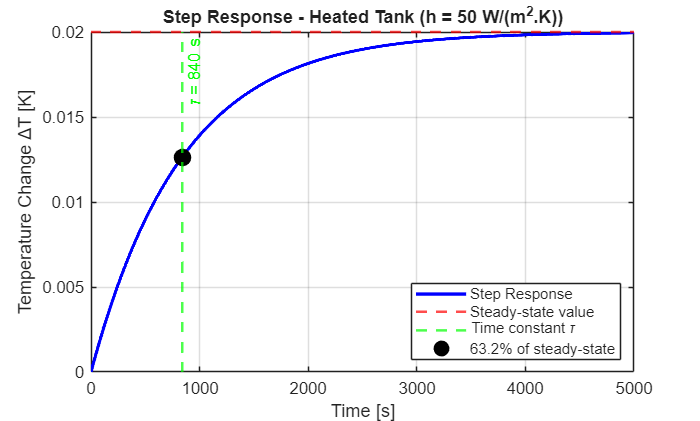

t = 0:1:5000;   % Time vector [s], up to 5000s for full response

[y1, t1] = step(G1, t);
[y2, t2] = step(G2, t);

% --- Figure 1: Individual Step Response for Case 1 ---
figure('Name', 'Case 1: Step Response (h=50)', 'NumberTitle', 'off');
plot(t1, y1, 'b-', 'LineWidth', 2);
hold on;
yline(K1, 'r--', sprintf('Steady-state = %.4f K/W', K1), 'LineWidth', 1.5);
xline(tau1, 'g--', sprintf('\\tau = %.0f s', tau1), 'LineWidth', 1.5);
plot(tau1, K1*(1 - exp(-1)), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
hold off;
xlabel('Time [s]');
ylabel('Temperature Change \DeltaT [K]');
title('Step Response - Heated Tank (h = 50 W/(m^2.K))');
legend('Step Response', 'Steady-state value', 'Time constant \tau', ...
       '63.2% of steady-state', 'Location', 'southeast');
grid on;

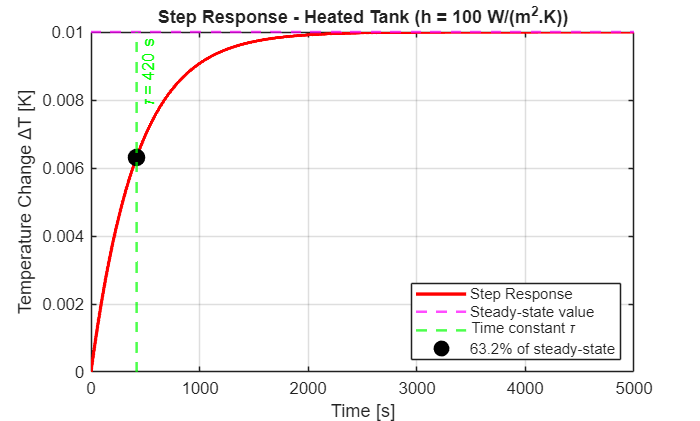


% --- Figure 2: Individual Step Response for Case 2 ---
figure('Name', 'Case 2: Step Response (h=100)', 'NumberTitle', 'off');
plot(t2, y2, 'r-', 'LineWidth', 2);
hold on;
yline(K2, 'm--', sprintf('Steady-state = %.4f K/W', K2), 'LineWidth', 1.5);
xline(tau2, 'g--', sprintf('\\tau = %.0f s', tau2), 'LineWidth', 1.5);
plot(tau2, K2*(1 - exp(-1)), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
hold off;
xlabel('Time [s]');
ylabel('Temperature Change \DeltaT [K]');
title('Step Response - Heated Tank (h = 100 W/(m^2.K))');
legend('Step Response', 'Steady-state value', 'Time constant \tau', ...
       '63.2% of steady-state', 'Location', 'southeast');
grid on;

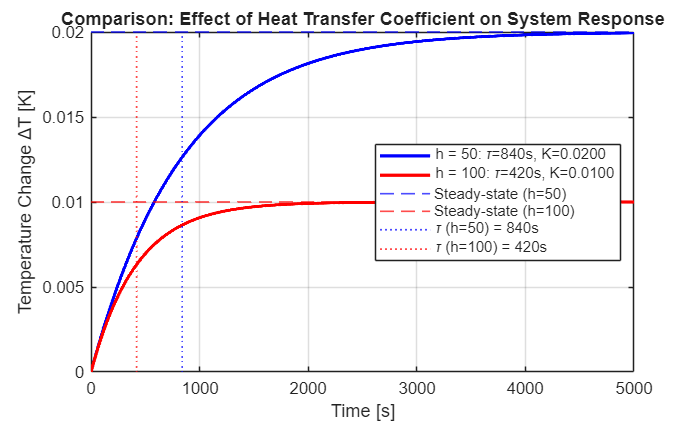


% --- Figure 3: Comparison of Both Cases ---
figure('Name', 'Comparison of Step Responses', 'NumberTitle', 'off');
plot(t1, y1, 'b-', 'LineWidth', 2); hold on;
plot(t2, y2, 'r-', 'LineWidth', 2);
yline(K1, 'b--', 'LineWidth', 1);
yline(K2, 'r--', 'LineWidth', 1);
xline(tau1, 'b:', 'LineWidth', 1);
xline(tau2, 'r:', 'LineWidth', 1);
hold off;
xlabel('Time [s]');
ylabel('Temperature Change \DeltaT [K]');
title('Comparison: Effect of Heat Transfer Coefficient on System Response');
legend(sprintf('h = %d: \\tau=%.0fs, K=%.4f', h1, tau1, K1), ...
       sprintf('h = %d: \\tau=%.0fs, K=%.4f', h2, tau2, K2), ...
       sprintf('Steady-state (h=%d)', h1), ...
       sprintf('Steady-state (h=%d)', h2), ...
       sprintf('\\tau (h=%d) = %.0fs', h1, tau1), ...
       sprintf('\\tau (h=%d) = %.0fs', h2, tau2), ...
       'Location', 'east');
grid on;

## Temperature Analysis Over Time

fprintf('\n=== Temperature Analysis Over Time ===\n');


=== Temperature Analysis Over Time ===


fprintf('At t = tau (1 time constant):\n');

At t = tau (1 time constant):


fprintf('  Case 1: DeltaT = %.4f K (63.2%% of %.4f)\n', K1*(1-exp(-1)), K1);

  Case 1: DeltaT = 0.0126 K (63.2% of 0.0200)


fprintf('  Case 2: DeltaT = %.4f K (63.2%% of %.4f)\n', K2*(1-exp(-1)), K2);

  Case 2: DeltaT = 0.0063 K (63.2% of 0.0100)



fprintf('\nAt t = 3*tau (3 time constants):\n');


At t = 3*tau (3 time constants):


fprintf('  Case 1 (t=%.0fs): DeltaT = %.4f K (95.0%% of %.4f)\n', 3*tau1, K1*(1-exp(-3)), K1);

  Case 1 (t=2520s): DeltaT = 0.0190 K (95.0% of 0.0200)


fprintf('  Case 2 (t=%.0fs): DeltaT = %.4f K (95.0%% of %.4f)\n', 3*tau2, K2*(1-exp(-3)), K2);

  Case 2 (t=1260s): DeltaT = 0.0095 K (95.0% of 0.0100)



fprintf('\nAt t = 5*tau (5 time constants, ~steady state):\n');


At t = 5*tau (5 time constants, ~steady state):


fprintf('  Case 1 (t=%.0fs): DeltaT = %.4f K (99.3%% of %.4f)\n', 5*tau1, K1*(1-exp(-5)), K1);

  Case 1 (t=4200s): DeltaT = 0.0199 K (99.3% of 0.0200)


fprintf('  Case 2 (t=%.0fs): DeltaT = %.4f K (99.3%% of %.4f)\n', 5*tau2, K2*(1-exp(-5)), K2);

  Case 2 (t=2100s): DeltaT = 0.0099 K (99.3% of 0.0100)


## Summary of Parameter Effect

fprintf('\n========================================\n');

fprintf('   EFFECT OF INCREASING h (50 -> 100)\n');

   EFFECT OF INCREASING h (50 -> 100)


fprintf('========================================\n');

fprintf('Time constant: %.0f s -> %.0f s (DECREASED by factor 2)\n', tau1, tau2);

Time constant: 840 s -> 420 s (DECREASED by factor 2)


fprintf('System gain:   %.4f -> %.4f (DECREASED by factor 2)\n', K1, K2);

System gain:   0.0200 -> 0.0100 (DECREASED by factor 2)


fprintf('\nSystem Speed:\n');


System Speed:


fprintf('  - Higher h makes the system FASTER (smaller tau)\n');

  - Higher h makes the system FASTER (smaller tau)


fprintf('  - System reaches steady state in half the time\n');

  - System reaches steady state in half the time


fprintf('\nSteady-State Value:\n');


Steady-State Value:


fprintf('  - Higher h REDUCES the steady-state temperature rise\n');

  - Higher h REDUCES the steady-state temperature rise


fprintf('  - More heat is lost to surroundings, so less temperature increase\n');

  - More heat is lost to surroundings, so less temperature increase


fprintf('========================================\n');